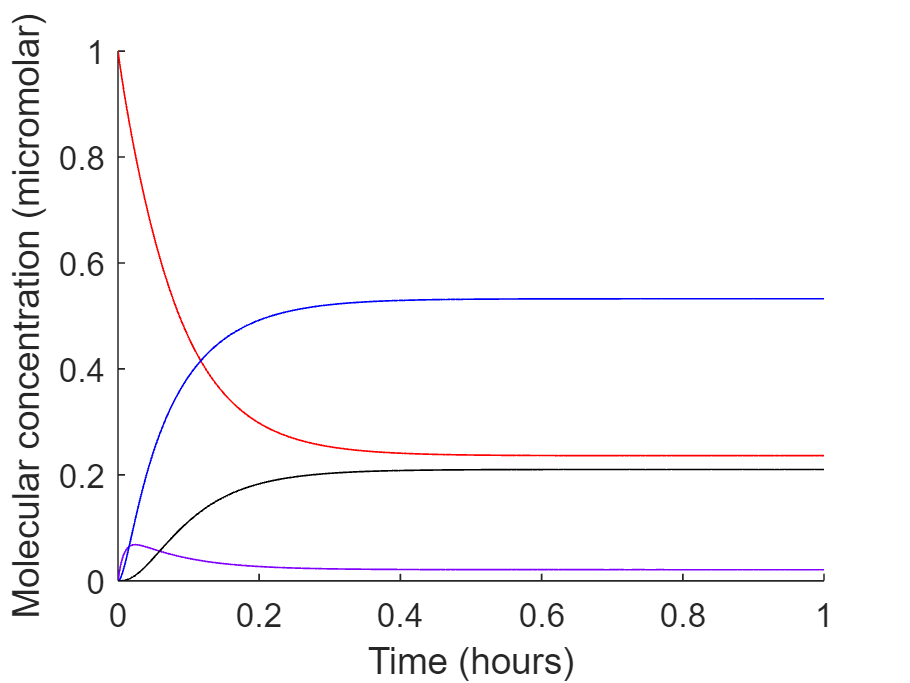


k_aon = 10;
k_aoff = 10;
k_ion = 10;
k_ioff = 10;
k_icat = 10;
k_acat = 100;
k_tot = 1;
p_tot = 1;

f1 = @(i,ik,a,ap) -k_ion*(k_tot-ik)*i +k_ioff*ik+k_icat*ap;

f2 = @(i,ik,a,ap) k_ion*(k_tot - ik)*i - k_ioff*ik - k_acat*ik;

f3 = @(i,ik,a,ap) -k_aon*(p_tot-ap)*a + k_aoff*ap + k_acat*ik;
 
f4 = @(i,ik,a,ap) k_aon*(p_tot-ap)*a - k_aoff*ap -k_icat*ap;

dxdt = @(t,x)[f1(x(1),x(2),x(3),x(4));
              f2(x(1),x(2),x(3),x(4));
              f3(x(1),x(2),x(3),x(4));
              f4(x(1),x(2),x(3),x(4))];
              

[T, X] = ode45(dxdt, [0,1], [1, 0, 0, 0]);

figure; hold on;
plot(T,X(:,1),'-r'); % red for i
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple for i which is specified bu [0.5 0 1]
plot(T, X(:,3),'-b');
plot(T,X(:,4), '-k');
ylabel('Molecular concentration (micromolar)')
xlabel('Time (hours)')

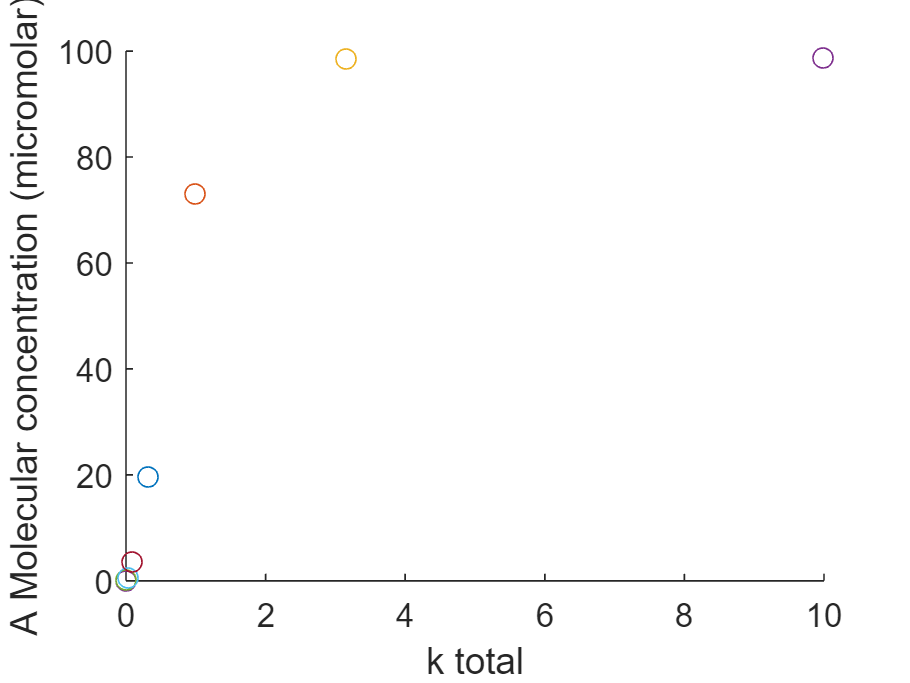

figure; hold on;
for n=10.^(-4:0.5:1)%log scale -4 to 2, optional third argument that goes in the middle that changes step size
    k_aon = 10;
    k_aoff = 10;
    k_ion = 10;
    k_ioff = 10;
    k_icat = 10;
    k_acat = 100;
    k_tot = n;
    p_tot = 1;
    
    f1 = @(i,ik,a,ap) -k_ion*(k_tot-ik)*i +k_ioff*ik+k_icat*ap;
    
    f2 = @(i,ik,a,ap) k_ion*(k_tot - ik)*i - k_ioff*ik - k_acat*ik;
    
    f3 = @(i,ik,a,ap) -k_aon*(p_tot-ap)*a + k_aoff*ap + k_acat*ik;
    
    f4 = @(i,ik,a,ap) k_aon*(p_tot-ap)*a - k_aoff*ap -k_icat*ap;
    
    dxdt = @(t,x)[f1(x(1),x(2),x(3),x(4));
                  f2(x(1),x(2),x(3),x(4));
                  f3(x(1),x(2),x(3),x(4));
                  f4(x(1),x(2),x(3),x(4))];
    
    
    [T, X] = ode45(dxdt, [0,1], [100, 0, 0, 0]);
   %i_tot is initial condition
    scatter(n, X(end,3));
end
ylabel('A Molecular concentration (micromolar)')
xlabel('k total')

%set(gca,'xscale','log')


function sse = finderror